# Physical properties static predictor

clear;
clc;

## Importing and Reviewing the Data

**A(i). Loading the data from the CSV file**

t95data = readtable("T95data");

%remove ID column since its redundant
t95data.ID = [];

**A(ii). What is sigificant about the sampled data period**

The data has a sampling time of 7 days, and was taken periodically at 2pm. This is historical data as evidenced in the large sampling time and long data span compared Distributed Control Systems. 

**A(ii). Plotting Variables as Time series**

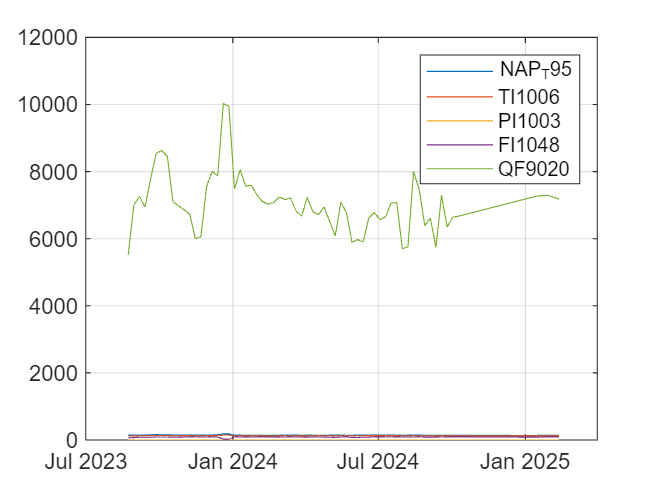

plotT95 = table2timetable(t95data);
figure
plot(plotT95.TimeStamp, plotT95.Variables)
legend(t95data.Properties.VariableNames(2:end))
grid on

Normalize Data to visualise plots more clearly

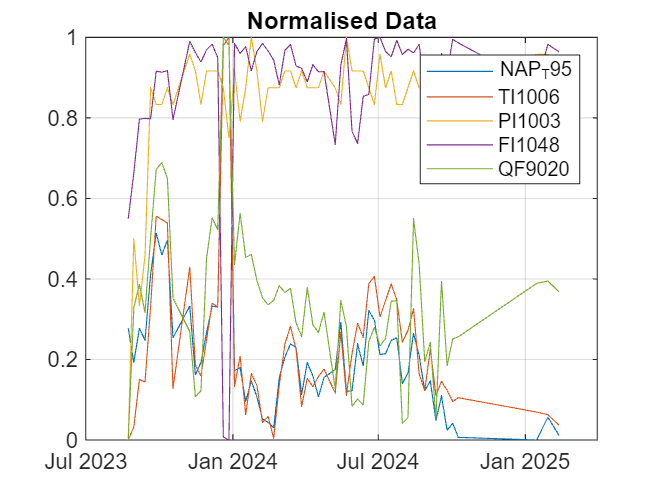

normT95 = normalize(plotT95.Variables,"range");
figure
plot(plotT95.TimeStamp, normT95)
legend(t95data.Properties.VariableNames(2:end))
title("Normalised Data")
grid on

The charts are too messy when viewed together. Plotting each physical quantity as timeseries. 

**1. The Naphta 95% Boiling Point Temperature - NAP_T95**

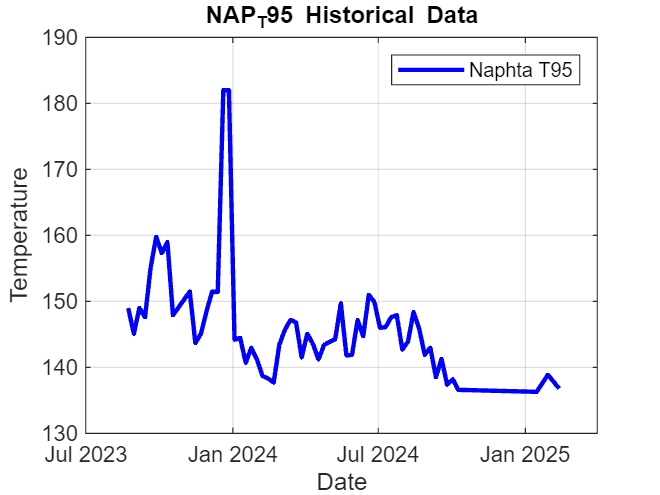

figure;
plot(plotT95.TimeStamp, plotT95.NAP_T95, "b-",LineWidth=2)
xlabel("Date")
ylabel('Temperature')
grid on
legend('Naphta T95')
title("NAP_T95 Historical Data")

**2. Chamber Temperature - TI1006**

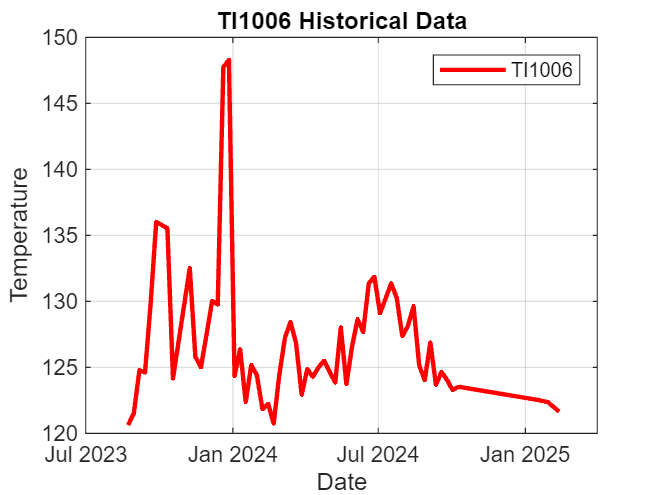

figure;
plot(plotT95.TimeStamp, plotT95.TI1006,"r-",LineWidth=2)
xlabel("Date")
ylabel('Temperature')
grid on
legend("TI1006")
title("TI1006 Historical Data")

**3. Chamber Pressure - PI1003**

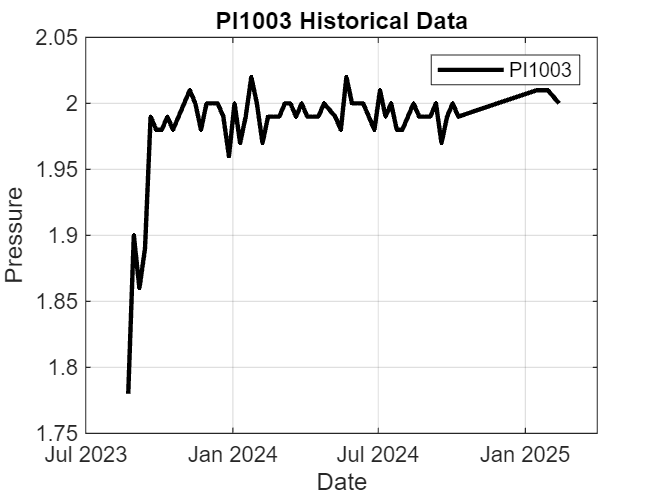

figure;
plot(plotT95.TimeStamp, plotT95.PI1003,"k-",LineWidth=2)
xlabel("Date")
ylabel('Pressure')
grid on
legend("PI1003")
title("PI1003 Historical Data")

**4. Flow Indicator - FI1048**

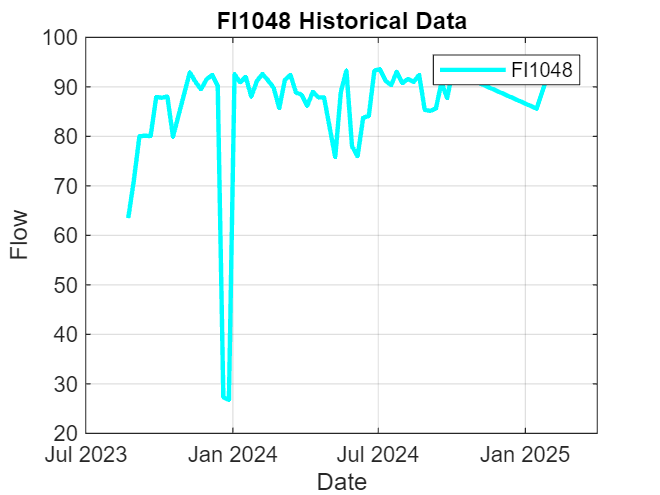

figure;
plot(plotT95.TimeStamp, plotT95.FI1048,"c-",LineWidth=2)
xlabel("Date")
ylabel('Flow')
grid on
legend("FI1048")
title("FI1048 Historical Data")

**5. ?? - QF9020**

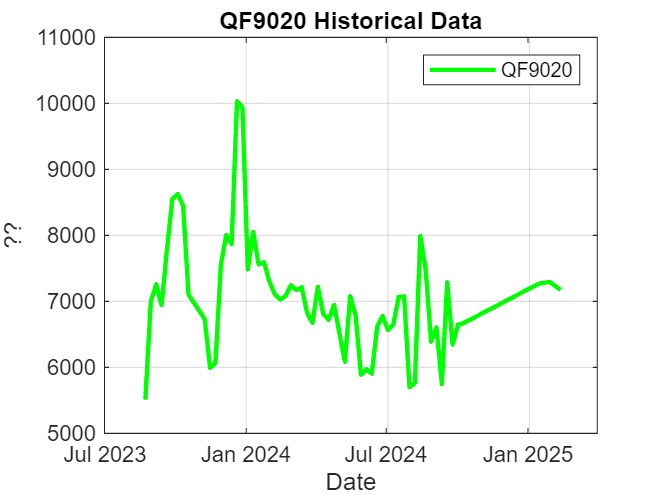

figure;
plot(plotT95.TimeStamp, plotT95.QF9020,"g-",LineWidth=2)
xlabel("Date")
ylabel('??')
grid on
legend("QF9020")
title("QF9020 Historical Data")

**A(iii). Which process variables appear to lack sufficient information for modelling**

Pressure: Since most pressure data lies between 1.9 and 2.2, it displays a major problem with historical data which is **lack of variation. **This makes modelling impossible. 

**A(iv). Assessing the variablility of the data using histograms**

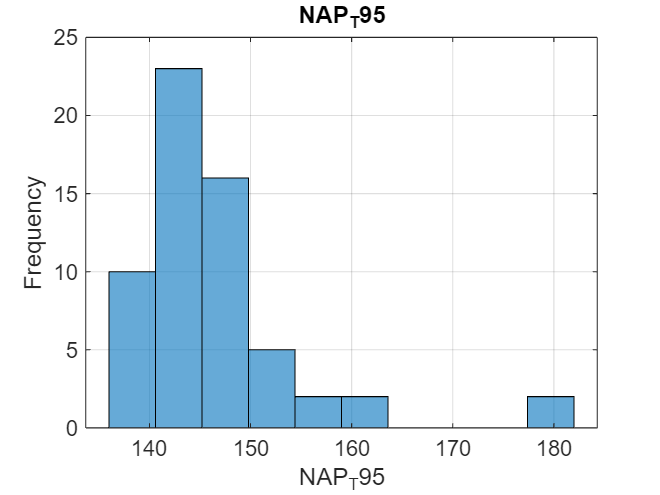

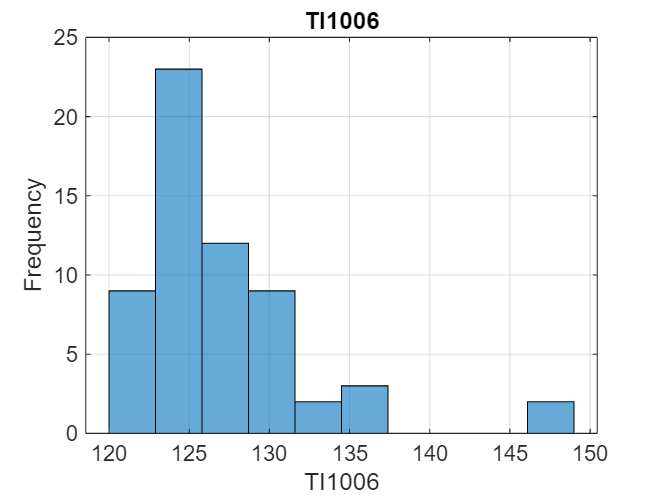

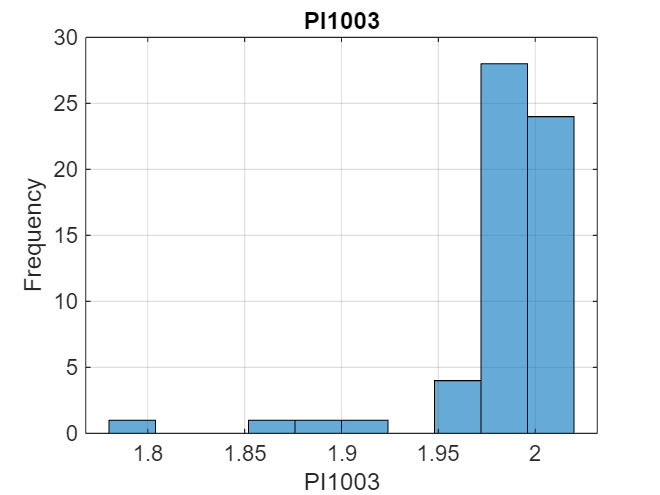

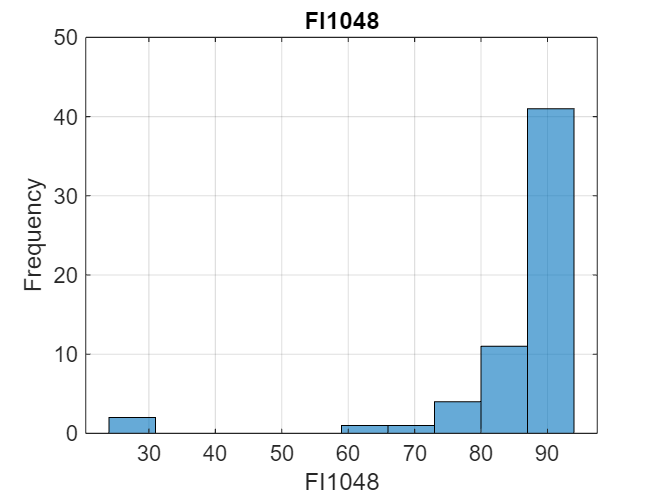

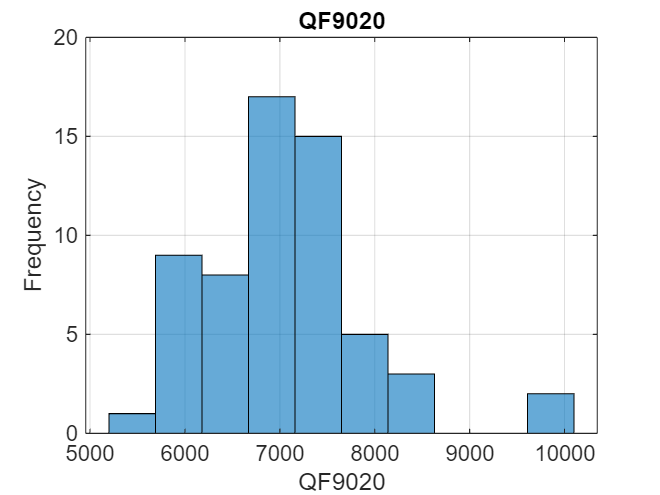

variables = plotT95.Variables;
variableNames = plotT95.Properties.VariableNames;
N = length(variableNames);
figure;
for i=1:5
    figure
    histogram(variables(:,i), 10)
    xlabel(variableNames{i})
    ylabel('Frequency')
    title(variableNames{i})
    grid on
end

**Naptha 95% and TI1006 TBC**

From the histogram, Naphta's 95% boiling point temperature and the chamber temperature seem to have medium variance, with 

**A(v). Possible Outliers in the Variables**

Using the histogram, we can see possible outliers these variables. 

Variable    Outlier (range)   Frequency

NAPT95     180                    2

TI1006        147                   2

PI1003        1.8                    1

FI1048         28                    1

The occurence of these values in all variables including QF9020 suggests that they are not outliers but the plant operating region was changed during a certain period. 

Outliers are important because they can distort results which such as increasing the mean or standard deviation. They can also signal rare events such as sensor faliure, change in operating region, or wrong operator inputs. 

Flow and Pressure show more extreme values towards the left of the histogram.

Using the IQR method of identifying outliers, we can further confirm possible Outliers in the data